# Gaussian processes

Here we will study Gaussian processes or random fields. We simulate spatial data, perform parameter estimation and prediction by Kriging interpolation.

## Task 1

This task will generate data to test the Kriging on. We generate uniformly distributed random sample locations within the unit square [0,1] [0,1]. The matern covariance matrix is calculated using the real parameter values. Its cholesky factorization is used to simulate measurements with the correct probability distribution at the sample locations.

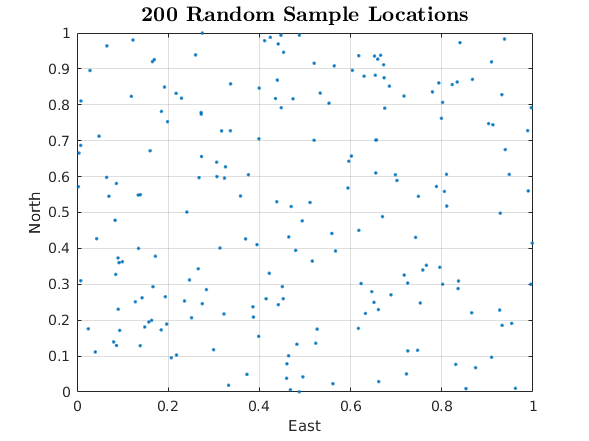

clc
close all
clear variables

m = 200;       % Number of measurments
sigma2 = 1;    % Covariance parameter
eta = 10;      % Covariance parameter
tau2 = 0.05^2; % Covariance parameter (Measurment Noise std)
alpha_true = 1;     % Regression parameter (Mean parameter)
theta_true = [sigma2; eta; tau2];

s_meas = rand(200,2); % locations.
figure(1);
plot(s_meas(:,1),s_meas(:,2),'.');
grid on;
title('\textbf{200 Random Sample Locations}', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('East'); ylabel('North');

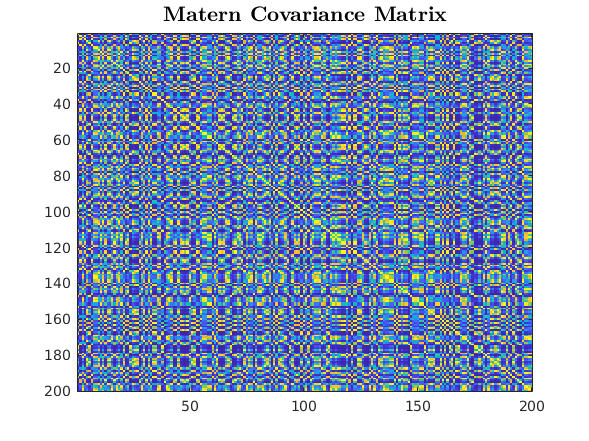


Sigma = generate_Sigma(theta_true, s_meas, m);

figure(2);
imagesc(Sigma);
title('\textbf{Matern Covariance Matrix}', 'Interpreter', 'latex', 'FontSize', 15);




Y = chol(Sigma)'*randn(m,1);    % Y ~ N(0,Sigma)

H = zeros(m,1);
for i = 1:m
    H(i) = (s_meas(i,1) - 0.5) + (s_meas(i,2) - 0.5);
end

Y = Y + alpha_true * H;             % Y ~ N(alpha*H,Sigma)

## Task 2

We use maximum likelihood estimation to estimate the parameters that were used to generate the data.

Log-likelihood of a multivariate gaussian distribution:


$$l\left(\mathbf{Y}\;\left|\;\alpha ,\theta \;\right.\right)=-\frac{1}{2}\log 
\;\left|\Sigma \right|-\frac{1}{2}\;{\mathbf{Z}}^{\prime } {\;\Sigma }^{-1} 
\;\mathbf{Z}$$


where


$$\mathbf{Z}=\mathbf{Y}-\mathbf{H}\alpha$$



$$\theta =\left\lbrack \begin{array}{ccc}\sigma^2  & \tau^2  & \eta \end{array}\right\rbrack$$


Estimating the parameters $\theta$ by maximization of the log-likelihood using newtons method:

Differentiations (first derivative and hessian) of the log-likelihood with respect to $\theta$:

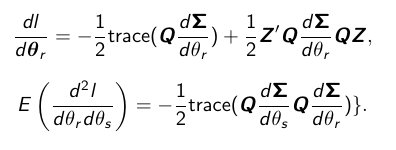

Differentiation of the log-likelihood with respect to $\alpha$:


$$\frac{d}{\mathrm{d}\alpha }l=-{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{H}\;\alpha 
+{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{Y}$$


Set to zero:


$$\begin{array}{l}\alpha^ˆ ={{\left({\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{H}\;\right)}^{-1} 
\;{\mathbf{H}}^{\prime } \;\mathbf{Q}\;\mathbf{Y}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;}^{\prime 
} \\\alpha^ˆ ={\mathbf{H}}^{-1} \;\mathbf{Y}\end{array}$$


NB: This estimated $\alpha$ is a function of $\theta$ thus we update them iteratively.


$$\beta =\alpha$$


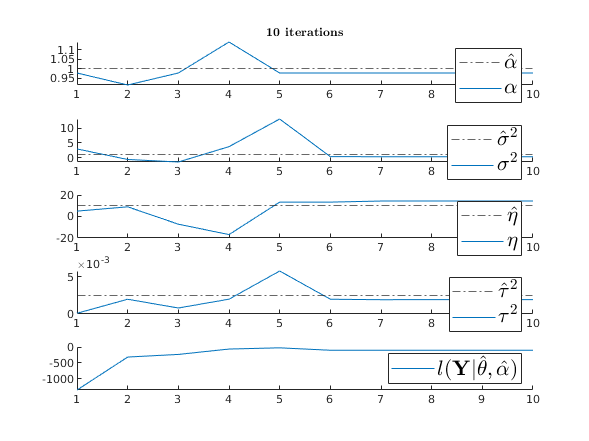

N_steps = 10;
theta = zeros(3,N_steps);
theta(:,1) = [3;5;0.0001];  % Initial guess
alpha = zeros(N_steps,1);
LogLikelihood = zeros(N_steps,1);
for i = 1:(N_steps -1)
    Sigma = generate_Sigma(theta(:,i), s_meas, m);
    %Q = Sigma\eye(m);
    %alpha(i) = H\Y 
    alpha(i) = (H'/Sigma*H)\(H'/Sigma*Y);
    %alpha(i) = (H'/Sigma*H)\(H'/Sigma*Y)
    Z = Y - H*alpha(i);
    LogLikelihood(i) = -0.5*log(norm(Sigma)) - 0.5*Z'/Sigma*Z;
    
    [dLogLikelihood, Hessian] = analythic_derivation(Sigma, Z,theta(:,i), s_meas, m);
    
    theta(:,i+1) = theta(:,i) - Hessian\dLogLikelihood;
end

Sigma = generate_Sigma(theta(:,i+1), s_meas, m);
alpha(i+1) = (H'/Sigma*H)\(H'/Sigma*Y);
Z = Y - H*alpha(i+1);
LogLikelihood(i+1) = -0.5*log(norm(Sigma)) - 0.5*Z'/Sigma*Z;
    
plotting_task2(theta, alpha, LogLikelihood, alpha_true, theta_true);

## Task 3

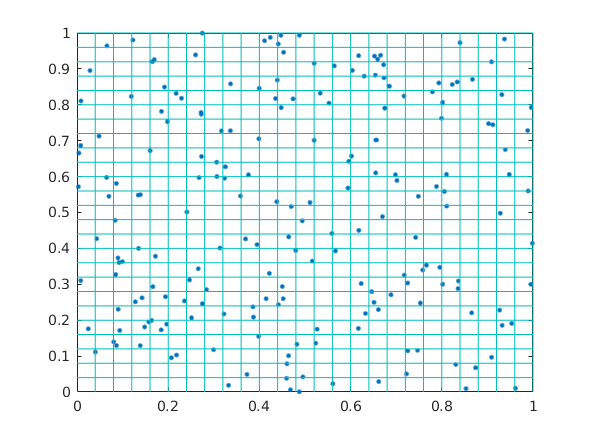

% Estimate s(s).
% C = Cov(i,j), C_0 = Cov(0,i).

grid_size = 25;

figure;
plot(s_meas(:,1),s_meas(:,2), '.', 'MarkerSize', 10);
hold on;
for i = 1:grid_size
    plot([0 1], [i*1/grid_size i*1/grid_size], 'color', [0, 0.75, 0.75], 'LineWidth', 0.5);
    plot([i*1/grid_size i*1/grid_size], [0 1], 'color', [0, 0.75, 0.75], 'LineWidth', 0.5);
end


% locations = zeros(1,625);
% j=0;
% for i = 1:grid_size:grid_size^2
%     locations(i+j)=1;
%     for j = 1:grid_size
%         locations(i+j)=j+1;
%     end
%     j=0;
% end
% locations = locations(1:end-1)';
%s_pred = zeros(grid_size^2, 2);
s_pred = [(0:0.04:1-0.04)', zeros(grid_size,1)];
for i=1:grid_size-1
    s_pred = [s_pred; (0:0.04:1-0.04)', 0.04*i*ones(grid_size,1)];
end



H_pred = zeros(grid_size^2, 1);
Sigma_0 = zeros(grid_size^2, m);
Sigma = generate_Sigma(theta_true,s_meas,m);
%Y_est = zeros(grid_size^2,1);
for i = 1:grid_size^2
    H_pred(i) = (s_pred(i,1) - 0.5) + (s_pred(i,2) - 0.5);
    Sigma_0(i,:) = generate_Sigma_pred(theta_true, s_pred(i,:), s_meas,m);
end

% Estimate Y as H_0*alpha_est + Sigma_0*Sigma^-1*(Y-H*alpha_est).
Y_est = H_pred*alpha(end) + (Sigma_0/Sigma)*(Y-H*alpha(end));

% Y-H*alpha(end)
% H_pred*alpha(end)
% (Sigma_0/Sigma)

% Compute new Sigma, called Sigma_0 in slides.
Sigma_x = generate_Sigma(theta_true,s_pred,grid_size^2);

% Pluginng Estimated alpha to compute prediction variance and std error.
std_err = diag(Sigma_x-(Sigma_0/Sigma)*Sigma_0');

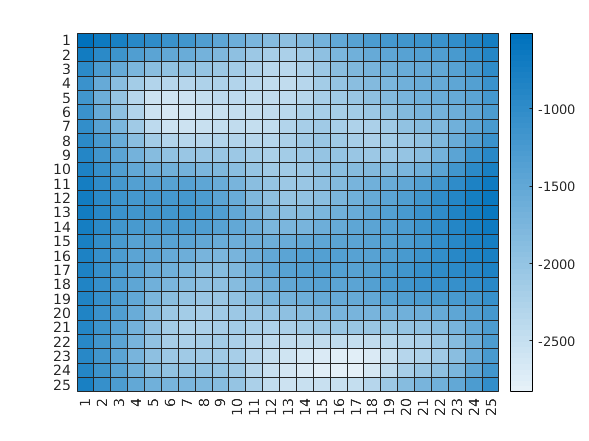

ans =   HeatmapChart with properties:

        XData: {25×1 cell}
        YData: {25×1 cell}
    ColorData: [25×25 double]

  Show all properties


% Reshape and plot std err.
std_err = reshape(std_err, [25 25]);
std_err = std_err';
figure
heatmap(std_err)

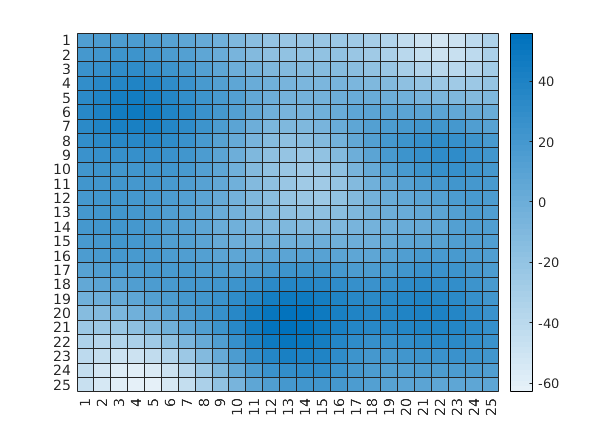

ans =   HeatmapChart with properties:

        XData: {25×1 cell}
        YData: {25×1 cell}
    ColorData: [25×25 double]

  Show all properties



% Reshape and plot estimated Y.
Y_grid = reshape(Y_est,[25,25]);
figure
heatmap(Y_grid')

%heatmap(Y_grid)
